# Preamble

clc, clear;

## Includes

addpath("../auxiliary/");
addpath("C:\ApostolatosFork\cane\generalMath");

## Analytical solution

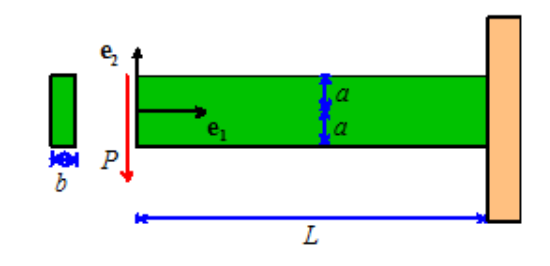

E = 1e7;
v = 0.31;
b=0.05; %thickness
a=0.2;
c=0;
P=100;
L=4;

d= (-P*L^3)/(2*E*a^3*b);
w = (3*P*L^2)/(4*E*a^3*b);

syms x1 x2 U1(x1, x2) U2(x1,x2) 
U1(x1, x2) = (3*P*(x1.^2).*x2-P*x2.^3*(2+v))/(4*E*a^3*b)+(3*P*a^2*x2)/(2*E*a^3*b) - w*x2 + c;
U2(x1, x2) = (-v*3*P*x1.*x2.^2-P*x1.^3)/(4*E*a^3*b) +w*x1 + d;
U_analytical = [U1;U2];

## Define the problem parameters

% Amplitude at the beam's ends
w0 = 0;

%material
propStruct.E = 1e7;
propStruct.v = 0.31;
propStruct.p = 7750*1e1; %kg/m3 (steel)
propStruct.g = 9.81; %(m/s2)

% Computational domain
propGeom.X0 = 0;
propGeom.XL = 4;
XComp = [propGeom.X0 propGeom.XL];

propGeom.Y0=0;
propGeom.YL=1;
YComp = [propGeom.Y0 propGeom.YL];


% Test cooordinates transformation
results = coordinateTransformationToXiAndEta(XComp',YComp');
results.scale_x;
results.const_x;
results.scale_y;
results.const_y;
detJ = determinantOfJacobian(results);

## Generate the training data

% points over which to enforce the boundary conditions by means of the loss
% of the neural network
numBC = 32;

% boundary conditions
% W(x=0 , y) = 0
X0BC = propGeom.XL * ones(1,numBC);
Y0BC = linspace(propGeom.Y0, propGeom.YL , numBC);
U0BC = w0*ones(2, numBC);

## Create some random points between the computational interval

numInternColl = 4*numBC^2;
pointSet = sobolset(2);
points = net(pointSet,numInternColl);
X = (XComp(1, 1) + points(:, 1)*(XComp(1, 2) - XComp(1, 1)))';
Y = (YComp(1, 1) + points(:, 2)*(YComp(1, 2) - YComp(1, 1)))';

## Find optimal penalty factor (PART A)

C = (propStruct.E /(1-propStruct.v^2))*[
    1 propStruct.v 0;
    propStruct.v 1 0;
    0 0 (1-propStruct.v)/2];

%% median value for the logspace vector
initFactor = norm(C)*numInternColl/numBC;

%% use logspace
vectorStart = 2*initFactor*1e-10;
vectorStop = 2*initFactor*1e+10;
logSpaceA = log10(vectorStart);
logSpaceB = log10(vectorStop);

possiblePenaltyFactor = logspace(logSpaceA, logSpaceB, 5);
calculateNorms = zeros(length(possiblePenaltyFactor), 1);

for iterator = 1:length(possiblePenaltyFactor)

## Deep learning model

% % Number of layers and Number of neurons per layer
numLayers = 5;
numNeurons = 15;

%%Create parameters as a struct
parameters = struct;

sz = [numNeurons 2];

% % initialize the weights and biases for the first fully connected operation
% The input layer has 2 neurons and numNeurons connections to the next layer
 parameters.fc1_Weights = initializeHe(sz, 2, "double");
 parameters.fc1_Bias = initializeZeros([numNeurons 1],"double");

% % Initialize the weights and biases for the hidden fully connected operations.
for layerNumber = 2:numLayers-1
    name = "fc"+layerNumber;

    sz = [numNeurons numNeurons];
    parameters.(name+"_Weights") = initializeHe(sz, numNeurons, "double");
    parameters.(name+"_Bias") = initializeZeros([numNeurons 1], "double");
end
 
% % Initialize the final fully connected operation. The output layer has 2 
% %  neurons and returns the predicted solution u(x,y) and w(x,y)
sz = [2 numNeurons];
parameters.("fc" + numLayers +"_Weights") = initializeHe(sz, numNeurons, "double");
parameters.("fc" + numLayers + "_Bias") = initializeZeros([2 1],"double");

## Test the initialized network

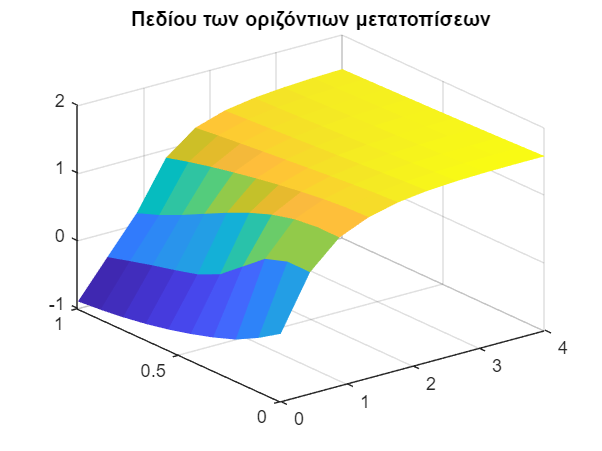

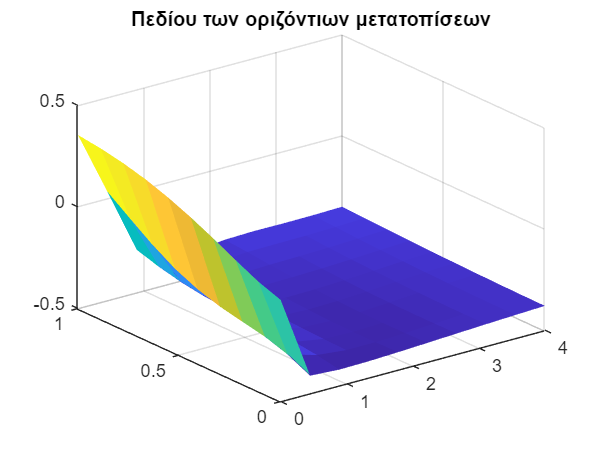

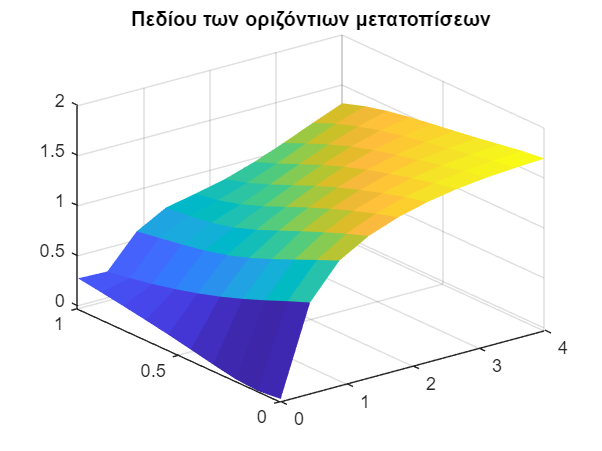

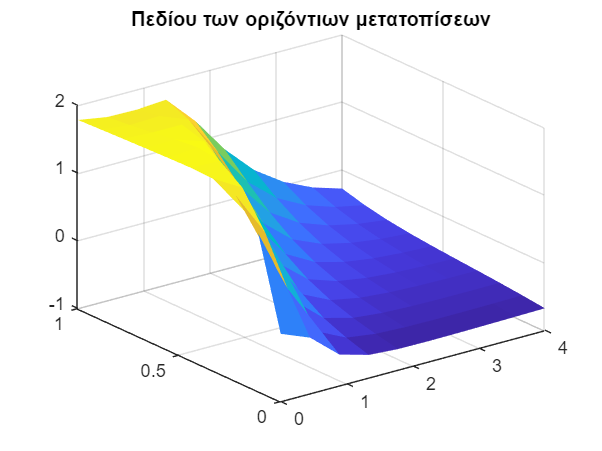

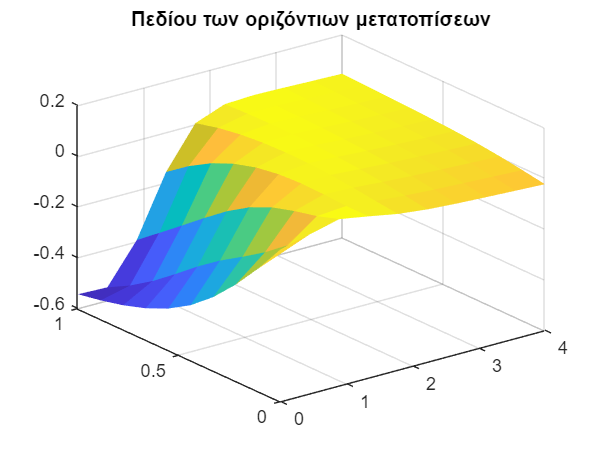

% dlU_test = model(parameters, dlarray(0.5, 'CB'), dlarray(0.1, 'CB'))
numPtsX = 10;
numPtsY = 10;
dX = (XComp(1, 2) - XComp(1, 1))/(numPtsX - 1);
dY = (YComp(1, 2) - YComp(1, 1))/(numPtsY - 1);
Xvct = repmat(XComp(1, 1):dX:XComp(1, 2), numPtsX, 1);
Yvct = repmat(transpose(YComp(1, 1):dY:YComp(1, 2)), 1, numPtsY);
dispX = zeros(numPtsX, numPtsY);
dispY = zeros(numPtsX, numPtsY);

for jj = 1:numPtsY
    for ii = 1:numPtsX
        disp = extractdata(model(parameters, dlarray(Xvct(ii, jj), 'CB'), dlarray(Yvct(ii, jj), 'CB')));
        dispX(ii, jj) = disp(1, 1);
        dispY(ii, jj) = disp(2, 1);
    end
end

figure
surf(Xvct, Yvct, dispX, "LineStyle","none")

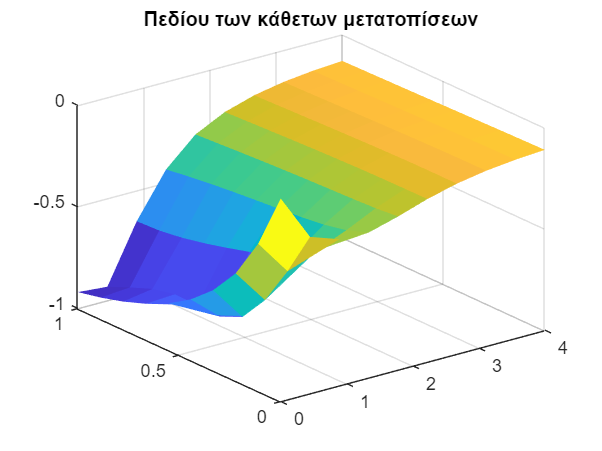

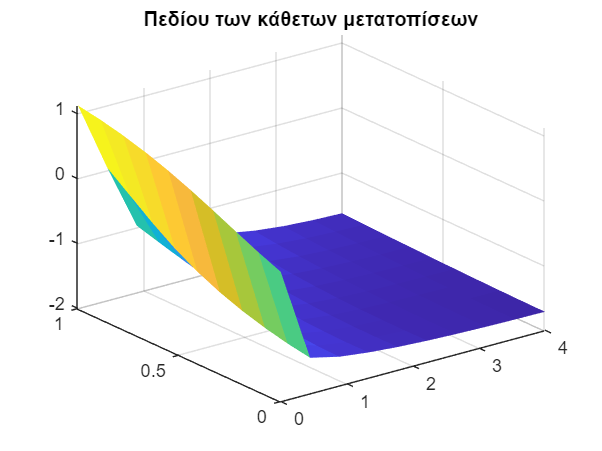

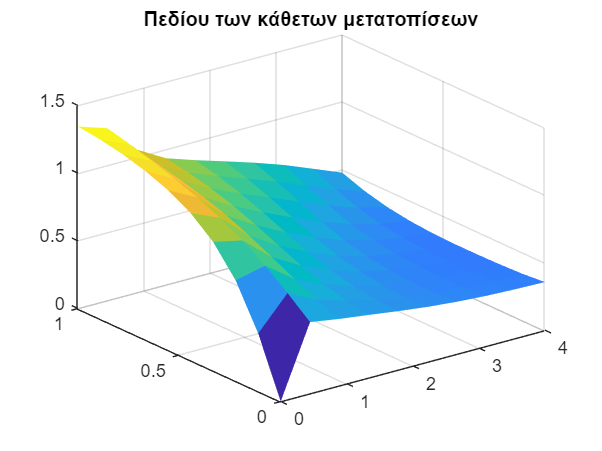

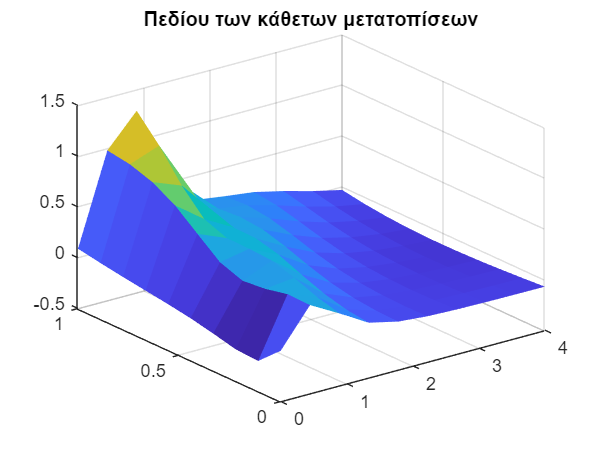

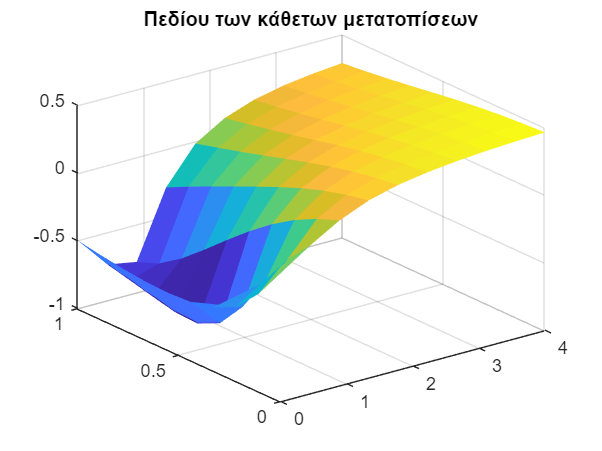

title("Πεδίου των οριζόντιων μετατοπίσεων")
figure
surf(Xvct, Yvct, dispY, "LineStyle","none")

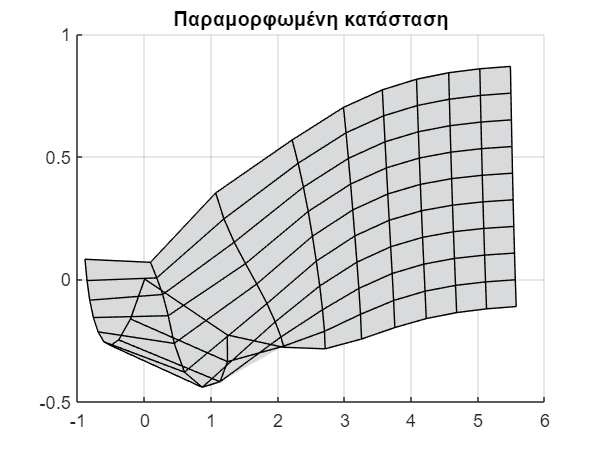

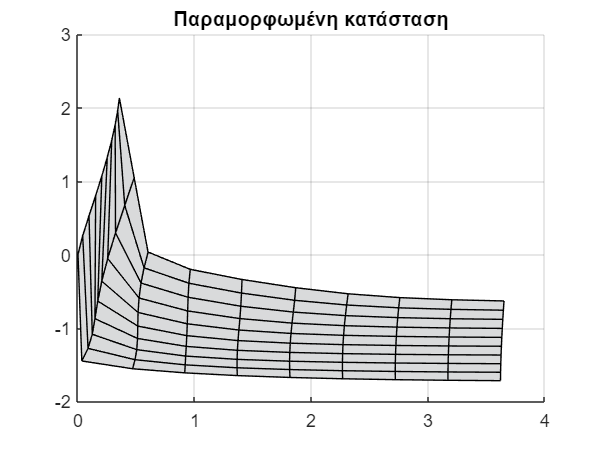

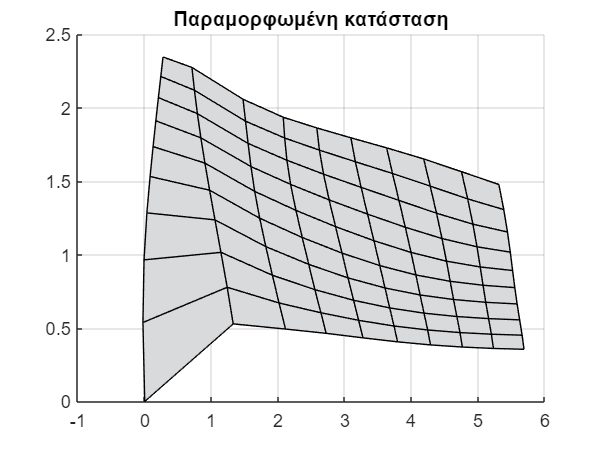

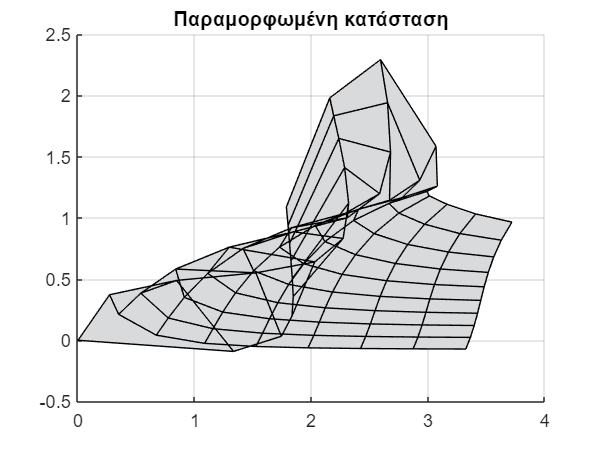

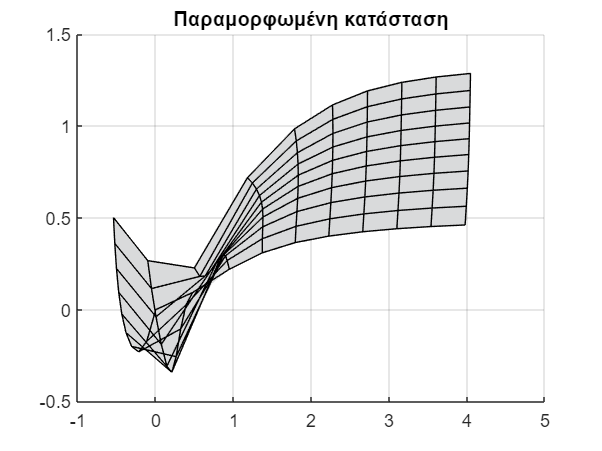

title("Πεδίου των κάθετων μετατοπίσεων")
figure
Xvct_curr = Xvct + dispX;
Yvct_curr = Yvct + dispY;

surf(Xvct_curr, Yvct_curr, zeros(numPtsX, numPtsY), "FaceColor", [217 218 219]/255);

view(2)
title("Παραμορφωμένη κατάσταση")

## Train the physics-informed neural network

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %% Specify the optimization options
opts = optimoptions('fmincon', ... % fminunc
    'HessianApproximation', 'lbfgs', ...
    'MaxIterations', 1000 , ... % 7500
    'MaxFunctionEvaluations', 1000, ... % 7500
    'OptimalityTolerance', 1e-12, ...
    'SpecifyObjectiveGradient', true, ...
    'UseParallel', false, ...
    'Display', 'iter');

% %% Train the network using fmincon

% % extract data and names from the parameters
[parametersV_init,parameterNames,parameterSizes] = parameterStructToVector( ...
    parameters);
parametersV_init = extractdata(parametersV_init);

% % Convert the training data to dlarray objects with format 'CB' (channel, batch).
dlX = dlarray(X,'CB');
dlY = dlarray(Y,'CB');
dlX0BC = dlarray(X0BC,'CB');
dlY0BC = dlarray(Y0BC,'CB');
dlU0BC = dlarray(U0BC,'CB');

%%Create a function handle with one input that defines the objective function.
objFun = @(parameters) objectiveFunction(parameters, dlX, dlY, dlX0BC, dlY0BC, dlU0BC, ...
    parameterNames, parameterSizes, propStruct, possiblePenaltyFactor, calculateNorms, iterator);

% Update the learnable parameters using the fmincon function
parametersConv = fmincon(objFun, parametersV_init, [], [], [], [], [], [], [], ...
    opts);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.404691e+14    0.000e+00    1.146e+15
    1      13    2.130776e+14    0.000e+00    6.784e+14    2.206e-01
    2      14    1.224007e+14    0.000e+00    2.836e+14    6.305e-02
    3      15    7.094749e+13    0.000e+00    7.702e+13    8.932e-02
    4      16    5.276427e+13    0.000e+00    1.151e+14    6.060e-02
    5      17    3.212062e+13    0.000e+00    1.738e+14    1.334e-01
    6      18    1.716096e+13    0.000e+00    6.257e+13    9.341e-02
    7      19    1.112993e+13    0.000e+00    2.589e+13    6.965e-02
    8      20    6.185158e+12    0.000e+00    1.382e+13    8.675e-02
    9      21    3.548297e+12    0.000e+00    1.277e+13    8.124e-02
   10      22    2.240096e+12    0.000e+00    1.311e+13    8.645e-02
   11      23    1.678033e+12    0.000e+00    5.281e+12    4.096e-02
   12      24    1.421775e+12    0.000e+00    4

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.938046e+14    0.000e+00    5.189e+14
    1       8    6.258577e+13    0.000e+00    1.098e+14    7.058e+00
    2       9    6.066349e+12    0.000e+00    1.558e+13    1.426e+00
    3      10    9.185026e+11    0.000e+00    2.836e+12    1.609e-01
    4      11    5.877538e+11    0.000e+00    1.874e+12    3.527e-02
    5      12    2.606336e+11    0.000e+00    7.156e+11    6.826e-02
    6      13    1.742897e+11    0.000e+00    4.276e+11    4.704e-02
    7      14    1.442748e+11    0.000e+00    1.864e+11    3.949e-02
    8      15    1.235896e+11    0.000e+00    1.563e+11    4.453e-02
    9      16    7.178241e+10    0.000e+00    2.741e+11    1.410e-01
   10      18    4.769650e+10    0.000e+00    2.655e+11    1.813e-01
   11      19    3.582098e+10    0.000e+00    1.392e+11    4.828e-02
   12      20    3.206715e+10    0.000e+00    4

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.624060e+14    0.000e+00    1.016e+15
    1       8    3.539679e+14    0.000e+00    8.025e+14    7.058e+00
    2      10    1.059870e+14    0.000e+00    4.223e+14    1.998e+00
    3      11    9.200015e+12    0.000e+00    1.640e+13    7.333e-01
    4      12    7.409575e+12    0.000e+00    1.347e+13    2.511e-02
    5      13    2.686152e+12    0.000e+00    4.943e+12    1.162e-01
    6      14    1.339119e+12    0.000e+00    2.217e+12    7.979e-02
    7      15    7.268809e+11    0.000e+00    1.320e+12    7.876e-02
    8      16    4.513003e+11    0.000e+00    1.268e+12    8.997e-02
    9      17    3.000783e+11    0.000e+00    7.534e+11    9.261e-02
   10      18    2.571666e+11    0.000e+00    3.788e+11    3.260e-02
   11      19    2.065942e+11    0.000e+00    2.933e+11    7.009e-02
   12      20    1.737386e+11    0.000e+00    1

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.897075e+15    0.000e+00    7.136e+15
    1       6    3.701074e+14    0.000e+00    3.663e+15    2.823e+01
    2       8    2.155838e+14    0.000e+00    3.991e+14    4.485e+00
    3      10    1.974634e+13    0.000e+00    1.201e+14    2.523e-01
    4      11    2.841624e+12    0.000e+00    4.352e+13    5.043e-02
    5      12    2.867026e+11    0.000e+00    3.365e+11    2.873e-02
    6      13    2.864845e+11    0.000e+00    4.431e+10    2.253e-04
    7      14    2.864817e+11    0.000e+00    4.481e+10    2.611e-05
    8      15    2.864792e+11    0.000e+00    4.502e+10    2.963e-05
    9      16    2.864667e+11    0.000e+00    6.434e+10    1.832e-04
   10      17    2.864398e+11    0.000e+00    1.305e+11    4.486e-04
   11      18    2.863624e+11    0.000e+00    2.479e+11    1.377e-03
   12      19    2.861565e+11    0.000e+00    4

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.782705e+18    0.000e+00    1.418e+19
    1      14    4.650682e+17    0.000e+00    5.103e+18    1.103e-01
    2      15    8.751751e+16    0.000e+00    5.309e+17    3.160e-02
    3      16    8.215102e+16    0.000e+00    3.226e+17    2.948e-03
    4      17    7.749493e+16    0.000e+00    3.233e+17    3.770e-03
    5      18    6.251474e+16    0.000e+00    5.999e+17    1.558e-02
    6      19    4.119880e+16    0.000e+00    8.602e+17    2.733e-02
    7      20    1.450022e+16    0.000e+00    5.916e+17    4.134e-02
    8      22    8.684594e+15    0.000e+00    4.518e+17    2.174e-02
    9      23    4.222971e+15    0.000e+00    5.484e+16    1.108e-02
   10      24    4.136245e+15    0.000e+00    5.444e+16    9.826e-04
   11      25    3.842546e+15    0.000e+00    6.526e+16    2.861e-03
   12      26    3.281395e+15    0.000e+00    9

% parametersVConv = fminunc(objFun, parametersV, opts);

% % For prediction convert the vector of parameters to a structure
parametersConv = parameterVectorToStruct(parametersConv, ...
    parameterNames, parameterSizes);

% % Export network into dat file for future use
% save ('2D_Beam.mat', 'parameters');
% 
% %% Auxiliary functions
%

## Test the converged network

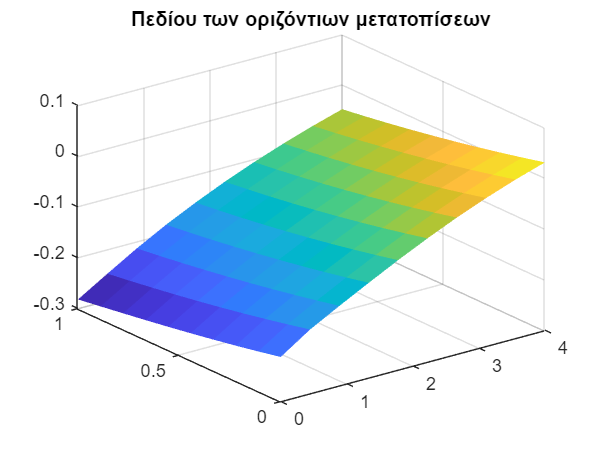

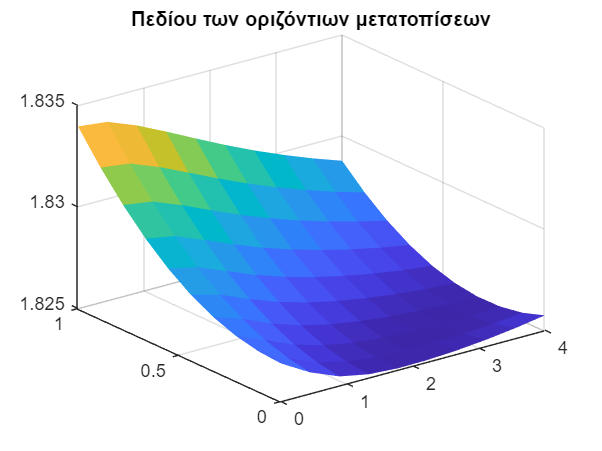

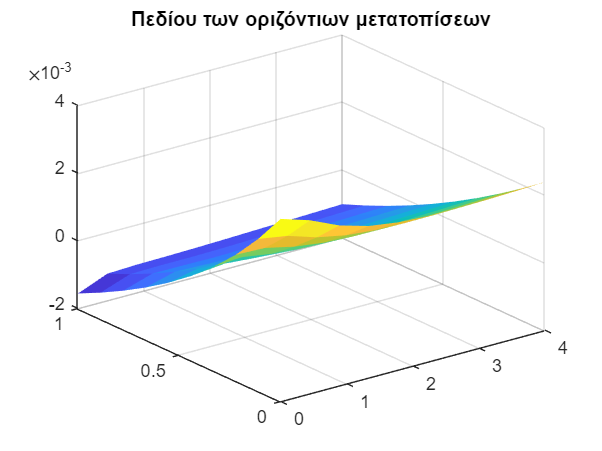

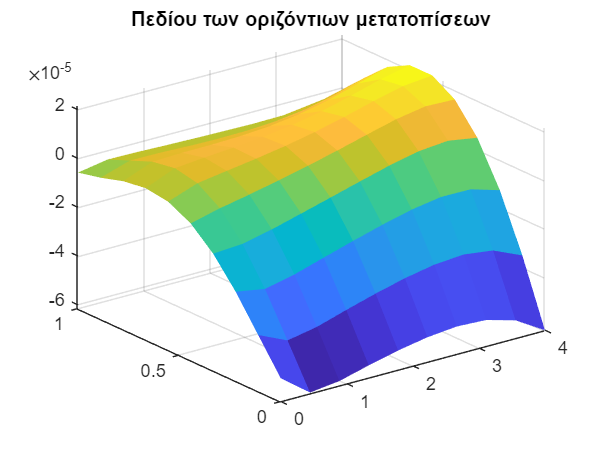

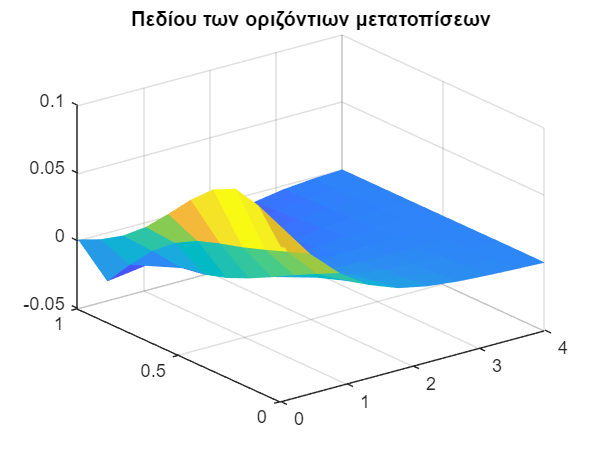

% dlU_test = model(parameters, dlarray(0.5, 'CB'), dlarray(0.1, 'CB'))
numPtsX = 10;
numPtsY = 10;
dX = (XComp(1, 2) - XComp(1, 1))/(numPtsX - 1);
dY = (YComp(1, 2) - YComp(1, 1))/(numPtsY - 1);
Xvct = repmat(XComp(1, 1):dX:XComp(1, 2), numPtsX, 1);
Yvct = repmat(transpose(YComp(1, 1):dY:YComp(1, 2)), 1, numPtsY);
dispX = zeros(numPtsX, numPtsY);
dispY = zeros(numPtsX, numPtsY);

for jj = 1:numPtsY
    for ii = 1:numPtsX
        disp = extractdata(model(parametersConv, dlarray(Xvct(ii, jj), 'CB'), dlarray(Yvct(ii, jj), 'CB')));
        dispX(ii, jj) = disp(1, 1);
        dispY(ii, jj) = disp(2, 1);
    end
end

figure
surf(Xvct, Yvct, dispX, "LineStyle","none")

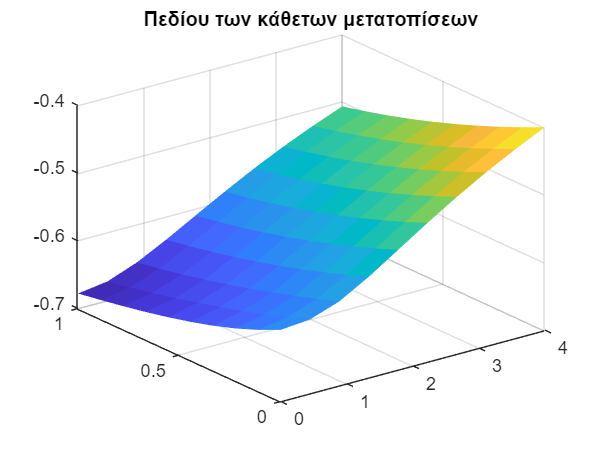

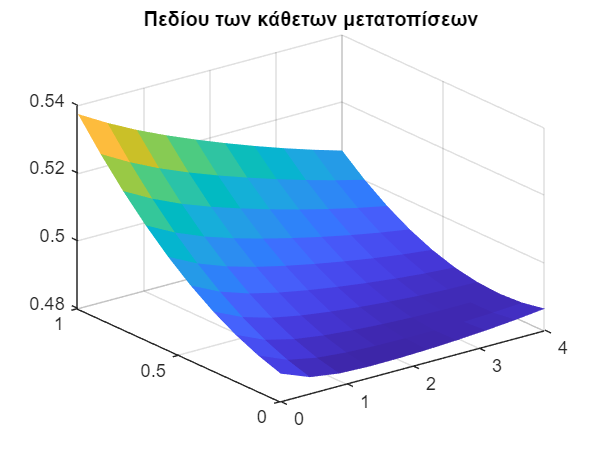

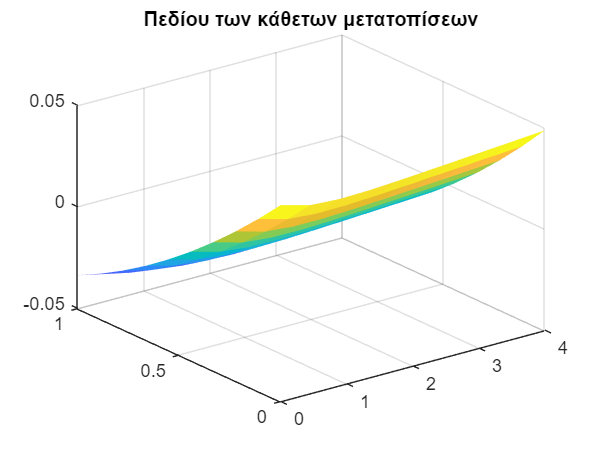

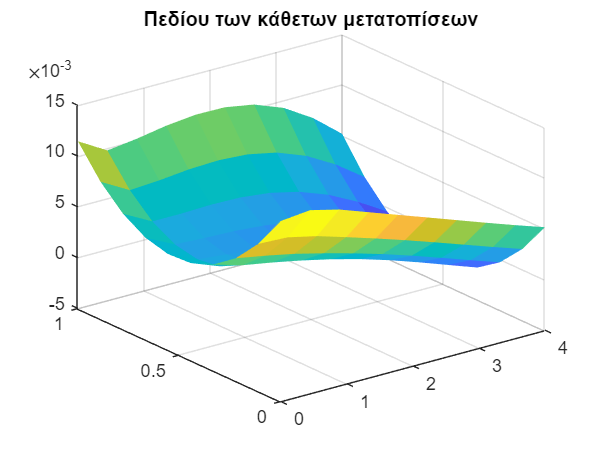

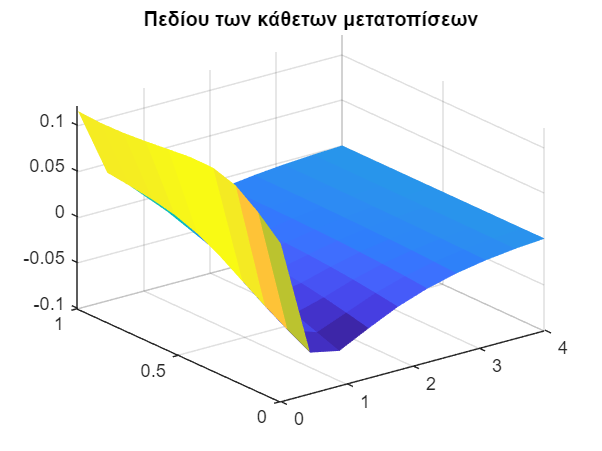

title("Πεδίου των οριζόντιων μετατοπίσεων")
figure
surf(Xvct, Yvct, dispY, "LineStyle","none")

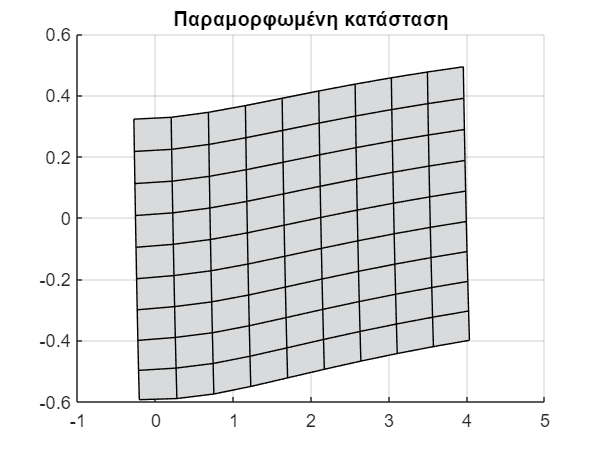

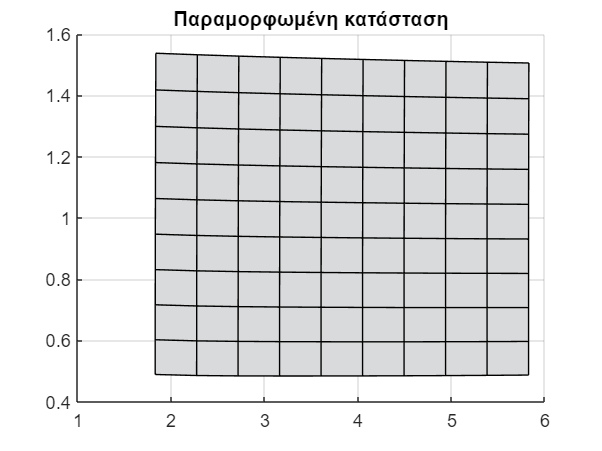

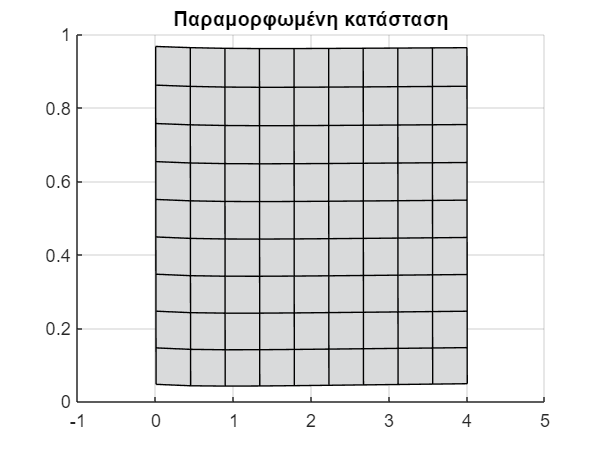

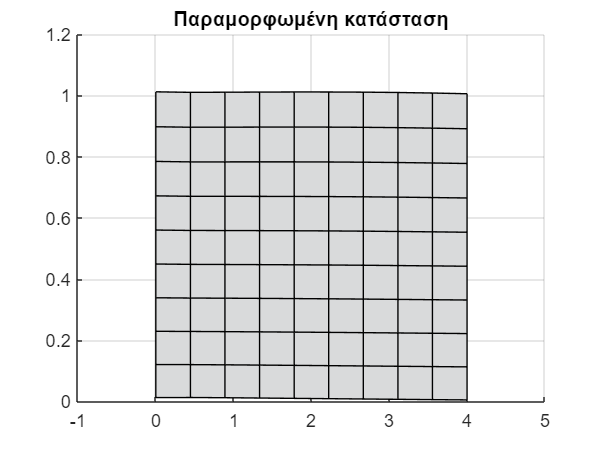

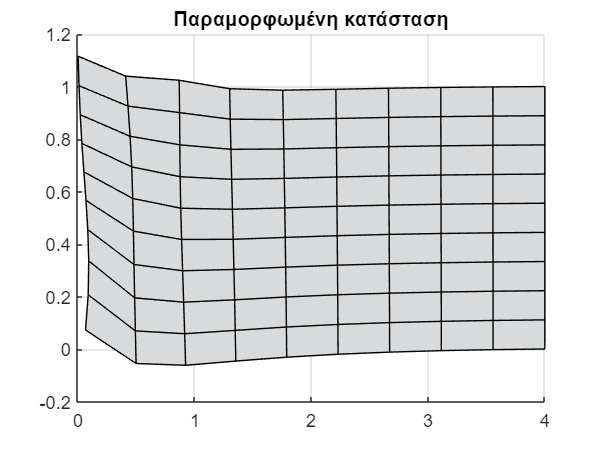

title("Πεδίου των κάθετων μετατοπίσεων")
figure
Xvct_curr = Xvct + dispX;
Yvct_curr = Yvct + dispY;

surf(Xvct_curr, Yvct_curr, zeros(numPtsX, numPtsY), "FaceColor", [217 218 219]/255);

view(2)
title("Παραμορφωμένη κατάσταση")

## Calculate L**2-Norm**

% Define number of Gauss points in which to calculate the norm
numGaussPts = 20;
[GP, GW] = getGaussPointsAndWeightsOverUnitDomain(numGaussPts);

x = repmat(GP, numGaussPts, 1);
y = repmat(transpose(GP), 1, numGaussPts);

% x = repmat(-1:dx:1, numGaussPts, 1);
% y = repmat(transpose(-1:dy:1), 1, numGaussPts);
result = 0;

for jj = 1:numGaussPts
    for ii = 1:numGaussPts
            result = result +  norm(detJ*GW(jj)*GW(ii)*(extractdata(model(parametersConv, dlarray(x(ii, jj), 'CB'), dlarray(y(ii, jj), 'CB')))-vpa(subs(U_analytical, [x1 x2], [x(ii, jj) y(ii, jj)]))))^2;
    end
end

% for jj = 1:numGaussPts
%     for ii = 1:numGaussPts
%             result = result +  (extractdata(model(parametersConv, dlarray(x(ii, jj), 'CB'), dlarray(y(ii, jj), 'CB')))-vpa(subs(U_analytical, [x1 x2], [x(ii, jj) y(ii, jj)]))).^2
%     end
% end
%%The L2 norm is:
result = sqrt(result);

## Find optimal penalty factor (PART B)

calculateNorms(iterator) = sqrt(result);
end

%% minimum L2 error
[minimumL2, indexFound]= min(calculateNorms);
optimalFactor = possiblePenaltyFactor(indexFound)

optimalFactor = 0.3710

## Define the objective function that optimizes for the weights and biases

function [loss, gradientsV] = objectiveFunction ...
    (parametersV, dlX, dlY, dlX0BC, dlY0BC, dlU0BC, parameterNames, parameterSizes, propStruct, possiblePenaltyFactor, calculateNorms, iterator)

    % Convert parameters to structure of dlarray objects
    parametersV = dlarray(parametersV);
    parameters = parameterVectorToStruct(parametersV, parameterNames, ...
        parameterSizes);
    % 
    % Evaluate model gradients and loss
    [gradients, loss] = dlfeval(@modelGradients, parameters, dlX, dlY, dlX0BC, dlY0BC, dlU0BC, ...
        propStruct, possiblePenaltyFactor, calculateNorms, iterator);    
    % Return loss and gradients for fmincon
    gradientsV = parameterStructToVector(gradients);
    gradientsV = extractdata(gradientsV);
    loss = extractdata(loss);
end

## Function that returns the loss and its gradient with respect to the weights and biases

function [gradients,loss] = modelGradients(parameters, dlX, dlY, dlX0BC, dlY0BC, dlU0BC, propStruct, possiblePenaltyFactor, calculateNorms, iterator)
        % Make predictions with the initial conditions
    dlU = model(parameters, dlX, dlY);

$\frac{\partial u_x}{ \partial X}$, $\frac{\partial u_y}{ \partial Y}$, $\frac{\partial u_x}{ \partial Y}$, $\frac{\partial u_y}{ \partial X}$

    d_dlUX_dx = dlgradient(sum(dlU(1, :),'all'), dlX, 'EnableHigherDerivatives', true);
    d_dlUY_dy = dlgradient(sum(dlU(2, :),'all'), dlY, 'EnableHigherDerivatives', true);
    d_dlUX_dy = dlgradient(sum(dlU(1, :),'all'), dlY, 'EnableHigherDerivatives', true);
    d_dlUY_dx = dlgradient(sum(dlU(2, :),'all'), dlX, 'EnableHigherDerivatives', true);

$\frac{\partial^2 u_x}{ \partial^2 X}$, $\frac{\partial^2 u_y}{ \partial^2 Y}$, $\frac{\partial^2 u_x}{ \partial^2 Y}$, $\frac{\partial^2 u_y}{ \partial^2 X}$

    dd_dlUX_dxdx = dlgradient(sum(d_dlUX_dx, 'all'), dlX, 'EnableHigherDerivatives', true);
    dd_dlUY_dydy = dlgradient(sum(d_dlUY_dy, 'all'), dlY, 'EnableHigherDerivatives', true);
    dd_dlUX_dydy = dlgradient(sum(d_dlUX_dy, 'all'), dlY, 'EnableHigherDerivatives', true);
    dd_dlUY_dxdx = dlgradient(sum(d_dlUY_dx, 'all'), dlX, 'EnableHigherDerivatives', true);

$\frac{\partial^2 u_x}{ \partial X \partial Y}$, $\frac{\partial^2 u_x}{ \partial Y \partial X}$,   $\frac{\partial^2 u_y}{ \partial X \partial Y}$, $\frac{\partial^2 u_y}{ \partial Y \partial X}$

    dd_dlUX_dxdy = dlgradient(sum(d_dlUX_dx, 'all'), dlY, 'EnableHigherDerivatives', true);
    dd_dlUX_dydx = dlgradient(sum(d_dlUX_dy, 'all'), dlX, 'EnableHigherDerivatives', true);
    dd_dlUY_dxdy = dlgradient(sum(d_dlUY_dx, 'all'), dlY, 'EnableHigherDerivatives', true);
    dd_dlUY_dydx = dlgradient(sum(d_dlUY_dy, 'all'), dlX, 'EnableHigherDerivatives', true);

$\frac{\partial \sigma _{xx}}{ \partial X}$, $\frac{\partial \sigma _{yy}}{ \partial Y}$, $\frac{\partial \sigma _{xy}}{ \partial Y}$, $\frac{\partial \sigma _{yx}}{ \partial X}$

    d_Sxx_dx = (propStruct.E/(1-propStruct.v^2))*(dd_dlUX_dxdx + propStruct.v*dd_dlUY_dydx);
    d_Syy_dy = (propStruct.E/(1-propStruct.v^2))*(propStruct.v*dd_dlUX_dxdy + dd_dlUY_dydy);
    
    d_Sxy_dy = (propStruct.E/(2*(1+propStruct.v)))*(dd_dlUX_dydy + dd_dlUY_dxdy);
    d_Syx_dx = (propStruct.E/(2*(1+propStruct.v)))*(dd_dlUX_dydx + dd_dlUY_dxdx);


$$f=\textrm{div}\sigma +b$$


    divStress = [d_Sxx_dx + d_Sxy_dy; d_Syy_dy + d_Syx_dx];
    b_const = - propStruct.p*propStruct.g;
    b = zeros(2, length(dlX));
    b = dlarray(b, 'CB');
    b(2, :) = b_const;

    % equilibrium eq.
    f = divStress + b;
%     f = divStress;
    
    %surf here!!!
    %loss f
    zeroTarget = zeros(size(f), 'like', f);
    lossF = mse(f, zeroTarget);


    % Compute the system response at the beam's left edge
    dlUBC = model(parameters, dlX0BC, dlY0BC);
%     lossU = mse(dlUBC, dlarray(zeros(2,32), 'CB'));
    lossU = mse(dlUBC, dlU0BC);
  
    %% LOSS
    % Total loss when searching for optimal penalty factor
    loss = lossF + possiblePenaltyFactor(iterator)*lossU;

     % Total loss when having already found penalty optimal factor
    %loss = lossF + optimalPenaltyFactor*lossU;

% Calculate gradients with respect to the learnable parameters.
    gradients = dlgradient(loss, parameters);
end

## Feed-forward (model) function for the neural network

function dlU = model(parameters, X, Y)

    dlXY = [X; Y];
    numLayers = numel(fieldnames(parameters))/2;
    
    % First fully connect operation.
    weights = parameters.fc1_Weights;
    bias = parameters.fc1_Bias;
    dlU = fullyconnect(dlXY,weights,bias);
    
%     % tanh and fully connect operations for remaining layers.
    for i = 2:numLayers
        name = "fc" + i;
    
        dlU = tanh(dlU);
    
        weights = parameters.(name + "_Weights");
        bias = parameters.(name + "_Bias");
        dlU = fullyconnect(dlU, weights, bias);
    end
    
end

## **Calculate the optimal penalty factor**

function transformationResults = coordinateTransformationToXiAndEta(x, y)   
        Xi=[-1; 1];
        Eta = [-1; 1];
        syms scale_x const_x scale_y const_y
        X = scale_x*x+const_x;
        Y = scale_y*y+const_y;
        eqns = [X == Xi, Y == Eta];
        r = solve(eqns, [scale_x const_x scale_y const_y]);
        transformationResults = r;
end

function detJ = determinantOfJacobian(results)
    syms Xi Eta
    x = (Xi-results.const_x)/results.scale_x;
    y = (Eta-results.const_y)/results.scale_y;
    J = [diff(x, Xi) diff(y,Xi);
           diff(x,Eta) diff(y,Eta)];
    detJ = det(J);
end